# Example for using the `rmse` function.

Copyright © 2021 Tamas Kis

Define the independent variable.

x = (0:0.5:10)';

Define the true data.

y = x.^2+4+mvnrnd(0,5,length(x));

Estimate the data using a model.

y_hat = x.^2+4;

Determine the root-mean-square error.

RMSE = rmse(y,y_hat)

RMSE = 2.8105

Plot the true and estimated values.

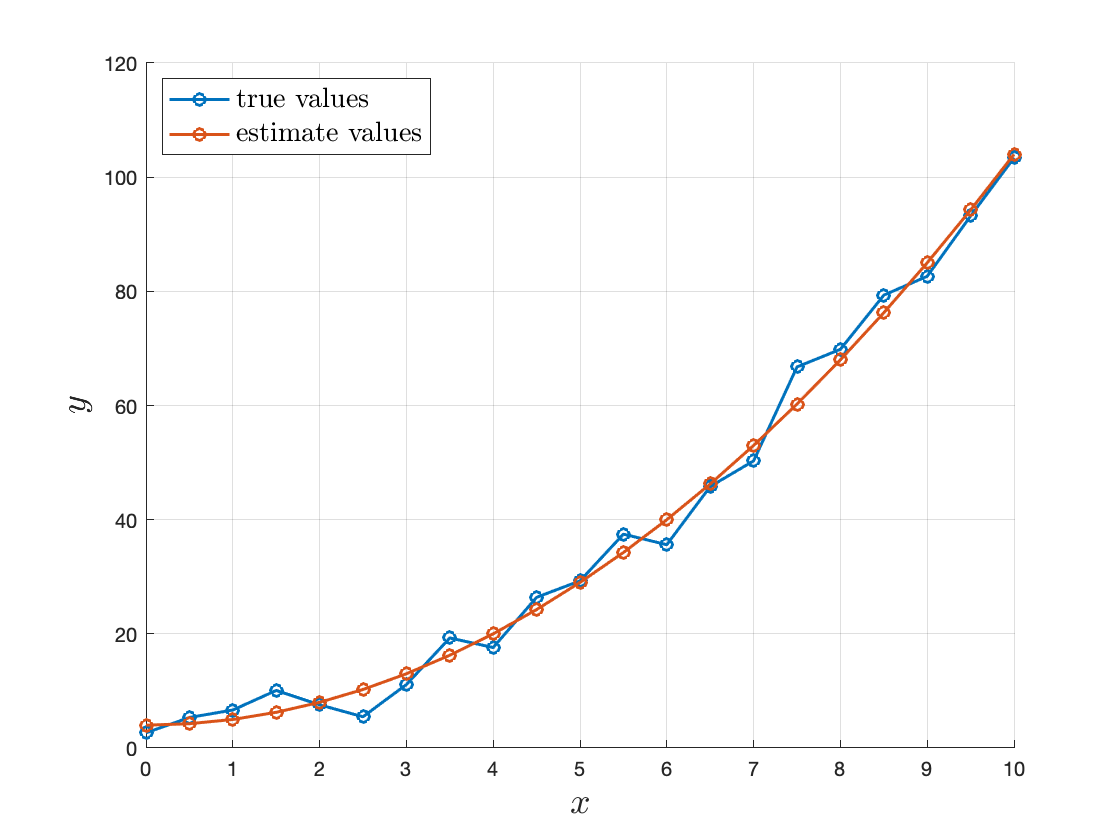

figure;
hold on;
plot(x,y,'-o','linewidth',1.5);
plot(x,y_hat,'-o','linewidth',1.5);
grid on;
hold off;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('true values','estimate values','interpreter','latex','fontsize',14,...
    'location','northwest');